## Prac 1

close all; clc; clear;

### Exercise 2

General Solution

syms t y(t)
dy2 = diff(y,t,2)

$$dy2(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)$$

dy = diff(y,t)

$$dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$

EQN = dy2 + dy + 4*y == exp(-t/2) % write the differential equation

$$EQN(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+\frac{\partial }{\partial t}y\left(t\right)+4\,y\left(t\right)={\mathrm{e}}^{-\frac{t}{2}}$$

xsol1 = dsolve(EQN)

$$xsol1 = \frac{4\,{\mathrm{e}}^{-\frac{t}{2}}}{15}+C_{1}\,{\mathrm{e}}^{-\frac{t}{2}}\,\cos\left(\frac{\sqrt{15}\,t}{2}\right)-C_{2}\,{\mathrm{e}}^{-\frac{t}{2}}\,\sin\left(\frac{\sqrt{15}\,t}{2}\right)$$

It has two free constants.

Particular Solution and Represent it with fplot

% Put the Initial Conditiont0 = ?; 
cond = [y(0) == 1, dy(0) == 1];
xsol2 = dsolve(EQN,cond)

$$xsol2 = \frac{{\mathrm{e}}^{-\frac{t}{2}}\,\left(11\,\cos\left(\frac{\sqrt{15}\,t}{2}\right)+3\,\sqrt{15}\,\sin\left(\frac{\sqrt{15}\,t}{2}\right)+4\right)}{15}$$

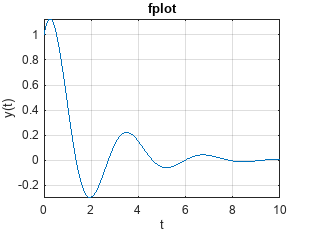

figure; fplot(xsol2,[0,10]);
xlabel('t');ylabel('y(t)');grid on; title('fplot')

Represent the symbolic solution as numeric function

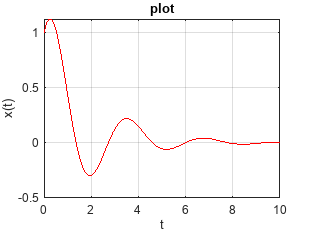

dt = 1e-2; ts = 0:dt:10; % Create a time vecto ts between 0 to 10 and dt=0.01
xs = double(subs(xsol2,t,ts)); % Evaluation de solution in ts
figure; plot(ts,xs,'r'); % Plot points (ts,xs) in red color
xlabel('t');ylabel('x(t)');grid on;title('plot')